# Process Aperture data

This calculates the following: accuracy, R^2, and response times (which includes significant changes in movement). 

clear all, close all

## Enter information below:

% sid = 'ecb43e';
sids = ['ecb43e'; 'fca96e'; 'cdceeb'];
comp = 'hyak'; % Other options: 'hyak' 'laptop' 'macademia'
chance = 1; % Turn on (1) or off (0) whether or not you're trying to calculate the chance values

## Computer specific info:

switch(comp)
    case 'macademia'
        dataPath = 'C:\Users\jcronin\Data\Subjects\';
        savePath = 'C:\Users\jcronin\Box Sync\Lab\ECoG\Aperture\Data Analysis\051016, for reviews\';
        addpath('C:\Users\jcronin\Code\Matlab\SigAnal');
        addpath('C:\Users\jcronin\Code\Matlab\Experiments\Aperture_Analysis\postprunedx3code');
    case 'hyak'
        dataPath = '../data/';
        warning('off', 'all'); % Turn off warnings if running on hyak to speed up processing
        set(0,'DefaultFigureVisible','off'); % Suppress figure display when running on hyak
        savePath = '../results/051016/';
        addpath('../SigAnal');
%         addpath('/postprunedx3code');
        addpath(genpath(pwd));
        parpool(16);
    case 'laptop'
        dataPath = '/Users/jcronin/Desktop/Data/';
        savePath = '/Users/jcronin/Desktop/Data/Results/';
        addpath('/Users/jcronin/Desktop/Code/SigAnal');
        addpath('/Users/jcronin/Desktop/Code/Experiments/Aperture_Analysis/postprunedx3code');
    otherwise
        error('unknown computer name entered');
end

# Start looping through subjects:

for ii=1:3
    sid = sids(ii,:);


## Subject specific info:

filePath: the path to the .mat files (converted from Tanks) for each subject; currently specific to Macademia computer

stims: the two stim channels: [active ground]

trials: useable trials from all Tank files (i.e. the runs that were actually completed)

trials_NV: the trials without visual feedback (i.e., trials with only stim feedback)

practiceTrials: 1: trials that have the straight beginning and then the sine wave begins halfway through the trial; 0: normal (sine) paths. This is used when determining the start and end times of the trial.

catchTrial: the trial number of the catch trial; 0 if no chance trial

switch(sid)
    case 'fca96e'
        filePath = strcat(dataPath, 'fca96e\data\d7\fca96e_Aperture\Matlab\Aperture-');
        stims = [4 5];
        trials = [2 5 7 8 9 10 12 13 15 16 17];
        trials_NV = [5 7 8 9 10 17];
        practiceTrials = [1 0 0 0 0 0 1 1 1 1 0];
        catchTrial = 0;
        
    case 'ecb43e'
        filePath = strcat(dataPath, 'ecb43e\d7\Aperture_ecb43e\Matlab_Aperture\Aperture_ecb43e-');
        stims = [47 46];
        trials = [4 5 6 8 9 10 11 12 13 14 15 16 18 19];
        trials_NV = [4 9 10 11 12 13 14 15 16 18 19];
        practiceTrials = zeros(size(trials)); % Did not have any practice trials as defined above
        catchTrial = 14;
        
    case 'cdceeb'
        filePath = strcat(dataPath, 'cdceeb(wrong-f3e511)\data\d14\Aperture_cdceeb\Matlab\ApertureCheck-');
        stims = [59 51];
        trials = [1 2 3];
        trials_NV = [1 2 3];
        practiceTrials = zeros(size(trials)); % Did not have any practice trials as defined above
        catchTrial = 0;
        
    otherwise
        error('unknown SID entered');
end

% Now switch the \ to / if on mac laptop or Hyak
if strcmp(comp, 'laptop') || strcmp(comp, 'hyak')
    filePath = strrep(filePath, '\', '/');
end

## Initialize vectors for saving trial by trial values

startTime and endTime: when to start and end the trial, cuts out data before the stim started and after the trial ended

accuracy and rsq (R^2) values for subject accuracy, average chance accuracy, and std deviations of the chance accuracies (run 1000 times)

responseTime: time (ms) from beginning of new stim (error) train to any 'significant change in motion'          CHECK THIS

responseTimeCorrect: time from beginning of new stim (error) train to any 'significant change in motion' that results in a desired correction (i.e. this is only the response times for when the subject correctly re-enters the target region) 

correctionTime: time (ms) from beginning of new stim (error) train to reentering the target region

- Each of the above (response times and correction times) has two cells: one for times from when they were too open, and one for times when they were too closed. 

startTime = zeros(length(trials), 1);
endTime = zeros(length(trials), 1);
accuracy = zeros(1, length(trials));
chanceAccuracy = zeros(1, length(trials));
std_chanceAccuracy = zeros(1, length(trials));
rsq = zeros(1, length(trials)); % This is for the R^2 from the original data starting from the entersTarget location
rsq2 = zeros(1, length(trials)); % This is for the R^2 from all original data
chanceRsq = zeros(1, length(trials));
std_chanceRsq = zeros(1, length(trials));
responseTime_open = cell(length(trials), 1);
responseTime_closed = cell(length(trials), 1);
responseTime_in = cell(length(trials), 1);
responseTimeTrains_open = cell(length(trials), 1);
responseTimeTrains_closed = cell(length(trials), 1);
responseTimeTrains_in = cell(length(trials), 1);
responseTimeCorrect_open = cell(length(trials), 1);
responseTimeCorrect_closed = cell(length(trials), 1);
correctionTime_open = cell(length(trials), 1);
correctionTime_closed = cell(length(trials), 1);
chanceResponseTimes = cell(length(trials), 3, 1000);
% chanceResponseTimes is a 3-D cell trials in rows and 3 columns for each of the response time variables (i.e. this holds the chance value for all of the responseTime_open, closed, and in variables)
% Those 3 columns go in the order listed above (starts with responseTime_open). The 3rd dimension is for the 1,000 simulated random walks that will be used
% for each calculation of the response times
pos_shuffled = cell(length(trials), 1);


# Loop through all trials for given subject and calculate: accuracy, R^2, and response times

for i=1:length(trials) %9:   9 (for testing good ecb43e trial)
    fileName = strcat(filePath, num2str(trials(i)));
    load(fileName);
    fs_aper = Aper.info.SamplingRateHz; % sampling rate of the stim data (Hz)
    t_aper = (0:1:length(Aper.data(:,1))-1)/fs_aper;
    fs_stim = Stim.info.SamplingRateHz;

Calculate the start and end times:

    if practiceTrials(i) == 1
        [startTime(i), endTime(i)] = aper_startANDendTimes(Aper.data(:,3), t_aper, 'yes');
    elseif practiceTrials(i) == 0
        [startTime(i), endTime(i)] = aper_startANDendTimes(Aper.data(:,3), t_aper, 'no');
    else
        error('practiceTrials array must only include 0s and 1s');
    end
    
    startSampAper = floor(startTime(i)*fs_aper);
    endSampAper = floor(endTime(i)*fs_aper);
    startSampStim = floor(startTime(i)*fs_stim);
    endSampStim = floor(endTime(i)*fs_stim);

Use the start and end times to redefine the data that we should use (this will then be used in all coming functions):

    % Aperture
    data = Aper.data(startSampAper:endSampAper,1);
    high_boundary = Aper.data(startSampAper:endSampAper,2);
    low_boundary = Aper.data(startSampAper:endSampAper,3);
    % Stim
    stimI = Stim.data(startSampStim:endSampStim, 4); % This is the stimulation current waveform that was set
    stimV= Stim.data(startSampStim:endSampStim, 5); % This is the stimulation voltage as monitored during delivery at the IZ
    % Times:
    t_aper = (0:1:length(data)-1)/fs_aper; % This was defined previously over the entire time range for use in the aper_startANDendTimes function; now redefining over just the period of interest
    t_stim = (0:length(stimI)-1)/fs_stim; % stim timing (s), starting from the starting Stim (armed) sample)

Calculate the accuracy:

This returns a matrix of the 1000 shuffled position vectors that will be used in the R^2 analysis

    % Accuracy:
    accuracy(i) = sum(data < high_boundary & data > low_boundary)/length(data);
    if chance % run chance calculations if they're turned on
        % Chance accuracy calculations:
        [pos_shuffled{i}, entersTarget, chanceAccuracy(i), std_chanceAccuracy(i)] = aper_chanceAccuracy(data, high_boundary, low_boundary);
    else
        entersTarget = 1; % If you don't run the chance calculation, you still need the entersTarget value - this is for debugging purposes and shouldn't be used for results.
    end
    

Calculate the R^2 values:  CHECK THESE!!

    % center_boundary is the 'ideal'/model path between the two low and high target boundaries
    center_boundary = (high_boundary(entersTarget:end) + low_boundary(entersTarget:end))./2;
    [rsq(i)] = lmrsquare(center_boundary, data(entersTarget:end));
    if chance
        % Chance R^2 calculations (use the same 1000 shuffled positions from accuracy calculation):
        [chanceRsq(i), std_chanceRsq(i)] = rsquare_chance(center_boundary, pos_shuffled{i});
    end
    
    %% Maybe should be calculating the true R2 value based on the entire path, not just from after they enter the target boundary... ?
    center_boundary2 = (high_boundary + low_boundary)./2;
    [rsq2(i)] = lmrsquare(center_boundary2, data);
    

## Calculate the significant changes in movement:

    % Get filtered signal and find the points of significant change in movement
    [locs_movement, data_interp, data_filt, dx3] = aper_coherence_3(data, fs_aper);

## Find when the stim state changes:

Using StimStarts and not StimTable, because StimTable still has issues with recognizing state changes. It does not handle finding state changes of no stim (i.e. it can only recognize when stim changes amplitude). Even then, it also can't handle/catch state changes when the stim amplitude changes in the middle of a train. For this type of code still use StimStarts. 

    ITI0 = max(Stm0.data(:,11));
    ITI1 = max(Stm1.data(:,11));
    if strcmp(sid, 'cdceeb')
        amp0 = max(Stm0.data(:,1))/2; % because amp was divided across two electrodes
        amp1 = max(Stm1.data(:,1))/2;
    else
        amp0 = max(Stm0.data(:,1));
        amp1 = max(Stm1.data(:,1));
    end
    PTD = max(Stm0.data(:,8));
    IPI = max(Stm0.data(:,5));
   % if trials(i) ~= catchTrial
   % When it's not the catch trial, then find the start of each stim state change
   % Don't do this for the catch trial because we use all the same stimulation so there won't be a state change
   
   % stimChanges don't matter for the catch trial because their aren't any stim state changes, but still calculate to avoid throwing errors later
   [stimChanges, stimPks, ~] = StimStarts(stimI, fs_stim, ITI0, ITI1, amp0, amp1, PTD, IPI, 'on');
    %end

Also find the start of each stim train for all types of trials. Do this by passing 'off' as the last parameter to StimStarts.

    [stimTrains, stimTrainPks, ~] = StimStarts(stimI, fs_stim, ITI0, ITI1, amp0, amp1, PTD, IPI, 'off');

Account for the **delay** between setting the stim output and recording stim output (StimStarts was based off of setting the IZ current output and there's delay between setting the current and getting the voltage change):

    % First find the first stim peak in the voltage monitor:
    [~, loc_realized] = findpeaks(stimV/max(stimV),'NPeaks',1, 'MinPeakHeight', 0.5);
    
    % Then find the first instance when a stimChanges value (calculated from the StimStarts and the set current)
    % is less than loc_realized starting from the end of the stimChanges (in order not to count any stimulations that
    % weren't actually delivered because the system wasn't armed. Then add the pulse width in samples to get to the last high
    % sample of the biphasic pulse. Also add the startSampStim since only after that point was considered in StimStarts and here we're considering it all:
    loc_set = find(stimTrains<loc_realized, 1, 'last');
    PW_samps = ceil(max(Stm1.data(:,2))*fs_stim*1e-6);
    loc_set = stimTrains(loc_set) + PW_samps-1;
    delay = abs(loc_realized-loc_set);
    
    % Add in the delay and
    % convert the stim start and end sample numbers from stim samples to Aperture
    % data samples (Aperture data was sampled slower):
    fac = fs_stim/fs_aper;
    stimChanges_delayed = stimChanges+delay;
    stimChanges_aperSamps = floor((stimChanges_delayed)/fac);
    stimTrains_delays = stimTrains+delay;
    stimTrains_aperSamps = floor((stimTrains_delays)/fac);
    
    % Visualize delay:
    figure(2), hold off
    subplot(3,1,1), plot(stimI/max(stimI), 'k')
    hold on, plot(stimV/max(stimV), 'r')
    scatter(loc_realized, stimV(loc_realized)/max(stimV), 'c', 'filled')
    scatter(loc_set, stimI(loc_set)/max(stimI), 'y', 'filled')
    title('Delay, not shifted'), legend('set current', 'realized V', 'first V peak', 'first current peak')
    
    subplot(3,1,2), plot(t_stim+delay/fs_stim, stimI/max(stimI), 'k')
    hold on, plot(t_stim, stimV/max(stimV), 'r')
    scatter(stimChanges_delayed/fs_stim, stimV(stimChanges_delayed)/max(stimV),'c','filled')
    title('Shifted, only armed portion plotted'), legend('set current', 'realized V', 'stim state changes'), xlabel('time (s)')
    % Note that the scattered stimChanges look like they're a little off, but this is only due to rounding error since I'm trying to plot in time
    
    subplot(3,1,3), plot(stimV/max(stimV), 'r')
    hold on, scatter(stimChanges_delayed, stimV(stimChanges_delayed)/max(stimV), 'c', 'filled')
    title('Voltage monitor with stim state changes'), legend('realized V', 'stim state changes')
    % Note that this one no longer has that rounding error shift in the stim changes

## Visualize the significant changes in motion and the stim state changes:

    figure(3), hold off
    plot(data, 'b'), hold on
    plot(data_filt, 'c')
    plot(high_boundary,'r'), plot(low_boundary,'r')
    scatter(stimChanges_aperSamps, data(stimChanges_aperSamps), 'g', 'filled')
    scatter(locs_movement, data(locs_movement,1), 'm', 'filled')
    title('Aperture data with stim state changes'), legend('data, original', 'data, smoothed', 'boundary', 'boundary','stim state change', 'movement change')

## Calculate the response times:

Response time from beginning of new stim (error) to any 'significant change in motion'

The cell should remain empty for any catch trials

    % Response timing, in ms
    % Use the last variable (0 or 1) to indicate whether the function should find just the first response time to the stim Change, or all of the responses (all=1)
    [responseTime_open{i}, responseTime_closed{i}, responseTime_in{i}] = aper_responseTime(locs_movement, stimChanges_aperSamps, stimPks, fs_aper, amp0, amp1, 1);
    
    % Chance response timing calculations (use the same 1000 shuffled positions from accuracy & R^2 calculations):
    % Don't run on catch trial because we're doing a different control on the catch trial, plus there aren's stim start changes in catch, so we'd have to run this differently for that trial. 
    if trials(i) ~= catchTrial && chance
        % Again, use the last variable (0 or 1) to indicate whether the function should find just the first response time to the stim Change, or all of the responses (all=1)
        chanceResponseTimes(i,:,:) = aper_responseTime_chance( stimChanges_aperSamps, stimPks, entersTarget,  pos_shuffled{i}, fs_aper, amp0, amp1, 1);
    end

Train response times from the start of each new stim train to the next significant change in motion. Note that if there are several consecutive stim train starts before a movement change, then the time of each stim train start to the movement change is counted, because we cannot be sure which train start the subject was really trying to respond to.

First discard and stim train starts that are the start of a state change, so that we have two separate groups: 1) stimChanges that are just the state changes, and 2) stimTrains that are just the starts of trains that do not start/represent state changes.

    ind = ismember(stimTrains_aperSamps,stimChanges_aperSamps);
    stimTrains_aperSamps = stimTrains_aperSamps(~ind);
    stimTrainPks = stimTrainPks(~ind);
    
    % Train response timing, in ms
    if trials(i) ~= catchTrial
        % when it's not the catch trial enter the stim amplitudes for the low and high intensities
        % We won't get anything for the too open state because there are no stim train starts there (too open state = no stim)
        % Since we don't have any stim train starts for the too open case, we'll instead choose random sample positions when the 
        % hand is in the too open state and calculate the response times from those, after add them into the stimTrains_aperSamps array
        temp=datasample(find(data>high_boundary),21);
        stimTrains_aperSamps = [stimTrains_aperSamps; temp];
        stimTrainPks = [stimTrainPks; zeros(21,1)];
        [responseTimeTrains_open{i}, responseTimeTrains_closed{i}, responseTimeTrains_in{i}] = aper_responseTime(locs_movement, stimTrains_aperSamps, stimTrainPks, fs_aper, amp0, amp1, 1);
    else
        % when it is the catch trial all of the stim trains are at the same amplitude, so we won't
        % try to classify them. Instead just pass the stim amp for the catch trials and return as the third output
        [~, ~, responseTimeTrains_in{i}] = aper_responseTime(locs_movement, stimTrains_aperSamps, stimTrainPks, fs_aper, max(Ctch.data(:,1)), 0, 1);
    end

Correct response times: those from the beginning of new stim (error) train to any 'significant change in motion' that results in the desired/correct correction (i.e. re-entering the target region): FINISH THIS!!!!!!!!!

    % Need to code this

Correction times from beginning of new stim (error) train to reentering the target region:

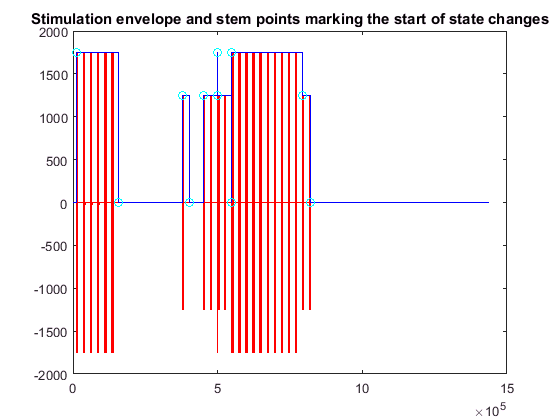

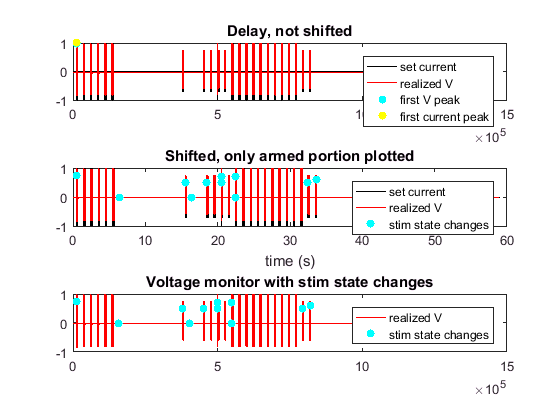

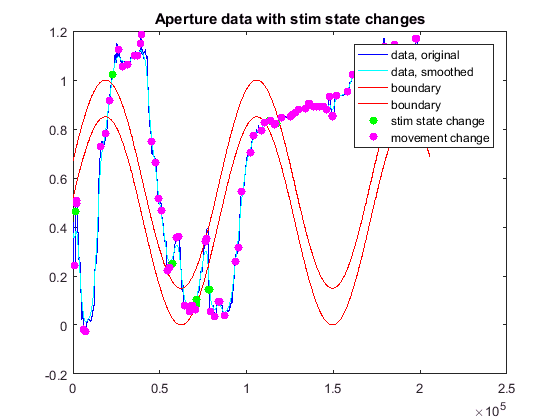

    % Correction timing: first find the sample numbers when the aper re-enters the target region from too open or too closed
    % This is actually the sample before the target is reentered, so add one
    locs_reenters_open = find(data(1:end-1)>high_boundary(1:end-1) & data(2:end)<high_boundary(2:end))+1;
    locs_reenters_closed = find(data(1:end-1)<low_boundary(1:end-1) & data(2:end)>low_boundary(2:end))+1;
    
    % Get correction time in ms:
    [correctionTime_open{i}, correctionTime_closed{i}] = aper_correctionTime(locs_reenters_open, locs_reenters_closed, stimChanges_aperSamps, stimPks, amp1, fs_aper);
end    

## Save variables

If the file already exists it will append a version number, and will always print out the final save path.  

savePath = strcat(savePath, sid);
% Append version number to the file name if it already exists:
if exist(strcat(savePath, '.mat'), 'file')~=0 % so if it does exist, append number
    temp=savePath;
    version=2;
    while exist(strcat(temp, '.mat'), 'file')~=0
        temp = strcat(savePath, '-v', num2str(version));
        version=version + 1;
    end
    savePath=temp;
end
print(savePath);
save(savePath, 'startTime', 'endTime', 'accuracy', 'chanceAccuracy', 'std_chanceAccuracy', 'rsq', 'rsq2',...
    'chanceRsq', 'std_chanceRsq', 'responseTime_open', 'responseTime_closed', 'responseTime_in',...
    'responseTimeTrains_open', 'responseTimeTrains_closed', 'responseTimeTrains_in',...
    'responseTimeCorrect_open', 'responseTimeCorrect_closed', 'correctionTime_open', 'correctionTime_closed',...
    'chanceResponseTimes', 'pos_shuffled');

end